# Image-Based Defect Detection for Manufacturing Inspection

In this project, you will use MATLAB to create a virtual inspection station that processes images of a single part type, produces defect evidence overlays and measurable features, and classifies parts using a pretrained network via transfer learning. You will then evaluate performance and robustness across a repeatable test suite.

Use this Live Script as a template to get started on your project solution. You may include helper functions at the bottom of this document or as separate files. For a tutorial on how to use Live Scripts, check out this [video](https://www.youtube.com/watch?v=hUXTyPYRidM).

**Suggested Tasks**

- Explore and Organize the Image Dataset

- Build a Single-Image Inspection Function

- Train and Integrate an AI Classifier into your Single-Image Inspection Function

- Evaluate Inspection System Performance

- Test and Evaluate System Robustness

## Break Down the Problem

In the space below, define the problem statement:

List the requirements, constraints, and success criteria for the project:

What is your proposed solution?

List the steps you will need to take to achieve your proposed solution:

What challenges do you face in the process of achieving the solution?

## Task 1: Explore and Organize Image Dataset (DONE)

Your goal in this step is to define defect classes and labels (keep it small).

- Load and inspect the images and labels from your chosen dataset (see the project page on GitHub for recommended datasets) to understand the part types, defect classes, and data balance

- Store labels in a table loaded by `readtable(...)`

- Manage images and labels with `imageDatastore(...)` and the `Labels` property (or use the example workflow for setting up labeled image datastores).

- Helpful reference: [Create and Explore Datastore for Image Classification](https://www.mathworks.com/help/deeplearning/ug/create-and-explore-datastore-for-image-classification.html).

- Choose 2-3 defect types (for FAIL) plus PASS

% Metal Parts Defect Detection Dataset

partsBS = imageDatastore("Datasets/metal_plate/test/", IncludeSubfolders=true, LabelSource="foldernames");
partsLabelsCount = countEachLabel(partsBS)

partsLabelsCount = 4×2 table
      Label       Count
    __________    _____

    good           26  
    major_rust     14  
    scratches      34  
    total_rust     23  


imageCount = length(partsBS.Labels);

srcName = {'good', 'major_rust', 'scratches', 'total_rust'};
targetNames = {'Metal Plate', 'Major Rust', 'Scratches', 'Total Rust'};
map = containers.Map(srcName, targetNames);

% Folder Structure
dataFolder = "Datasets/metal_plate/test";
imds = imageDatastore(dataFolder, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Remaps labels if the foldernames aren't canonical
labels = cellstr(imds.Labels);
for i = 1:numel(labels)
    key = labels{i};
    if isKey(map, key)
        labels{i} = map(key);
    end
end
imds.Labels = categorical(labels);

% Saves Labels Table
T = table(imds.Files, cellstr(imds.Labels), 'VariableNames', {'File', 'Label'});
writetable(T, fullfile(dataFolder, 'labels_table.csv'));

% Check counts per class and view example images to verify labeling.
counts = countEachLabel(imds);
disp(counts);

       Label       Count
    ___________    _____

    Major Rust      14  
    Metal Plate     26  
    Scratches       34  
    Total Rust      23  




%% Merge FAIL subclasses for Binary Evaluation
binaryLabels = cellstr(imds.Labels);
isFail = ismember(binaryLabels, {'Major Rust', 'Scratches'});
binaryLabels(isFail) = {'FAIL'};
binaryLabels(~isFail) = {'PASS'};

Tbinary = table(imds.Files, binaryLabels, 'VariableNames', {'File','BinaryLabel'});
writetable(Tbinary, fullfile(dataFolder,'labels_table_binary.csv'));

## Task 2: Build a Single-Image Inspection Function (MOSTLY DONE)

Your goal in this step is to create a function that analyzes and image to identify and quantify suspected defects detected in the image. You're trying to answer the question: "What in the image looks suspicious?"

To build this function you will need to:

**STEP 1. Standardize the images**

- Read images with `imread(...)` or through `imageDatastore(...)`.

- Standardize size with `imresize(...)` so metrics and model input are consistent.

- Convert to grayscale with `rgb2gray(...)` as needed (e.g. classical processing may rely on intensity values)

**STEP 2. Preprocess the images**

- Apply classical preprocessing, prioritizing stability over complexity. In other words, apply only what you need to reduce sensitivity to normal station variation. Suggested processing includes:

- Lighting correction: `imflatfield(...)` (or background estimate with `imgaussfilt(...)` and subtraction)

- Contrast normalization: `adapthisteq(...)`

- Denoising: `medfilt2(...)` or `imgaussfilt(...)`

- Save intermediate results during development (e.g., `imshowpair(...)`) for quick debugging.

**STEP 3. *****Optionally*****, define a region of interest (ROI)**

If each image already contains a centered part with minimal clutter, skip ROI and use the full image:

- `roi = I;`

If needed, define ROI fully automatically (no per-image manual selection), by using, for example:

- Fixed crop defined once (camera is consistent): indexing or `imcrop(...) `OR

- Auto-crop from the part mask: segment the part, compute `BoundingBox` using `regionprops(...)`, then `imcrop(...)`.

**STEP 4. Segment the image for an evidence overlay**

Your goal is to generate an evidence overlay and a few measurable numbers—not a perfect segmentation. Generate a simple binary mask that highlights suspicious regions in the image. Use a defect-appropriate recipe and keep it short:

- Start with thresholding: `imbinarize(...)` or `adaptthresh(...)` + `imbinarize(...)`

- Clean small specks: `bwareaopen(...)`

- Bridge gaps (if appropriate): `imclose(...)`

- Fill holes (only when it matches your goal (e.g., for a clean outer part silhouette): `imfill(...,'holes')`

Deliverable: `maskEvidence = defectEvidence(roi)`

**STEP 5. Extract a small set of interpretable metrics**

Your goal is to quantify the evidence for suspected defects, which supports traceability and debugging in your workflow. These metrics should answer the question: “What did the algorithm see, and how strong was the evidence?”

These measurements are mainly for traceability (inspection logs), debugging, and sanity checks. Keep it to 3–4 metrics so it stays easy.

Recommended minimal metrics (works for many defect types):

- `numComponents`: how many separate suspicious regions were found (use `bwconncomp(maskEvidence)` and read `NumObjects`)

- `maxArea`: size of the largest suspicious region (use `regionprops(maskEvidence,'Area')`)

- `areaRatio`: fraction of the ROI flagged as suspicious (`nnz(maskEvidence) / numel(maskEvidence)`)

- *(optional)* `edgeDensity`: if your evidence comes from edges (chips/scratches), measure how “edgy” the ROI is (`nnz(edgeMask) / numel(edgeMask)`)

**STEP 6. *****Optionally*****, implement a rule-based baseline.**

Implement 2–3 conservative rules so your system can always produce an explainable fallback decision mechanism. This can also be a useful comparison with AI result.

- Example: fail if `maxArea > Amax` or `numComponents > Nmax`

Deliverable: `baselineDecision = decideRules(evidence)`

function [numComponents, maxArea, areaRatio] = InspectImage(img)
    % Single-image Inspection Function to identify and quantify defects
    % Inputs:
    %   img           - Classifiable image, preferably RGB
    % Outputs:
    %   numComponents - Number of defects
    %   maxArea       - Max area of all defects
    %   areaRation    - Fraction of the image flagged as suspicious

    defectMask = PreprocessImage(img);

    % Connected components analysis on defects/rust
    cc = bwconncomp(defectMask);
    numComponents = cc.NumObjects;
    
    rp = regionprops(cc, "Area");
    areas = [rp.Area];

    if isempty(areas)
        maxArea = 0;
    else
        maxArea = max(areas);
    end
    
    areaRatio = nnz(defectMask) / numel(defectMask);
    
    % Display side-by-side comparison
    % imshowpair(img, defectMask, "montage");
    % title(sprintf('Defects: %d | Max Area: %d px', numComponents, maxArea));
end

function defectMask = PreprocessImage(image)
    if ~isa(image, 'uint8')
        image = im2uint8(image);
    end

    % =========================================================================
    % STEP 1: CLEAR CANVAS / BACKGROUND
    % =========================================================================
    hsvI = rgb2hsv(image);
    labI = rgb2lab(image);
    L = rgb2gray(image);
    sat = hsvI(:,:,2);
    val = hsvI(:,:,3);
    a = labI(:,:,2);
    b_lab = labI(:,:,3);

    fgMask = (sat > 0.08) | (val < 0.75 & sat > 0.03);
    fgMask = bwareaopen(fgMask, 350);

    % =========================================================================
    % STEP 2: CLEAR HOOK / HANGING WIRE (Robust Isolation)
    % =========================================================================
    R_chan = double(image(:,:,1));
    G_chan = double(image(:,:,2));
    
    % Target bright, color-neutral metallic wire components
    wireCandidate = (L > 85) & (sat < 0.15) & (abs(R_chan - G_chan) < 15);
    
    ccWire = bwconncomp(wireCandidate);
    statsWire = regionprops(ccWire, 'MajorAxisLength', 'MinorAxisLength', 'Area');
    hookMask = false(size(wireCandidate));
    
    for k = 1:ccWire.NumObjects
        maj = statsWire(k).MajorAxisLength;
        minr = max(statsWire(k).MinorAxisLength, 1);
        if (maj / minr > 3.0) || (statsWire(k).Area < 4000)
            hookMask(ccWire.PixelIdxList{k}) = true;
        end
    end
    
    % Dilate generously to fully cover the wire and its shadow edges
    hookMask = imdilate(hookMask, strel('disk', 6));
    
    % Strip the hook out of the canvas immediately
    cleanFg = fgMask & ~hookMask;

    % =========================================================================
    % STEP 3: FIND PLATE (Leave holes open to exclude the center mount hole)
    % =========================================================================
    plateMask0 = bwareaopen(cleanFg, 5000);
    ccp = bwconncomp(plateMask0);
    
    if ccp.NumObjects > 1
        statsP = regionprops(ccp, 'Area');
        [~, idx] = max([statsP.Area]);
        plateMask = false(size(plateMask0));
        plateMask(ccp.PixelIdxList{idx}) = true;
    else
        plateMask = plateMask0;
    end

    % =========================================================================
    % STEP 4: DETECT DEFECTS
    % =========================================================================
    I = im2double(image);
    R = I(:,:,1); G = I(:,:,2); Bc = I(:,:,3);
    isBlue = (Bc - R > 0.08) & (Bc - G > 0.05);

    % Use plateMask directly (unfilled) so the center mounting hole is excluded
    candidateDefects = plateMask & ~isBlue;
    
    bright = L > 200;
    rust = (b_lab > 10) & (a < 5);
    candidateDefects = candidateDefects | (plateMask & (bright | rust));

    % Safety filter to strip out any leftover wire pixels
    isGreyWire = (L > 85) & (sat < 0.15) & (abs(R_chan - G_chan) < 15);
    candidateDefects = candidateDefects & ~isGreyWire;

    candidateDefects = bwareaopen(candidateDefects, 250);
    se = strel('disk', 3);
    candidateDefects = imclose(candidateDefects, se);
    candidateDefects = imopen(candidateDefects, se);

    cc = bwconncomp(candidateDefects);
    stats = regionprops(cc, 'Area', 'MajorAxisLength', 'MinorAxisLength', 'Solidity');
    for i = 1:cc.NumObjects
        maj = stats(i).MajorAxisLength;
        minr = max(stats(i).MinorAxisLength, 1);
        ar = maj / minr;
        if stats(i).Area < 300 || ar > 5 || stats(i).Solidity < 0.2
            candidateDefects(cc.PixelIdxList{i}) = 0;
        end
    end

    defectMask = logical(candidateDefects);
end

## Task 3: Train and Integrate an AI Classifier into your Single-Image Inspection Function (DONE)

Your goal in this step is to use a MathWorks provided pretrained network (recommended: `resnet18`) to classify each part as either a PASS or FAIL, that will be part of the output of the function you began to build in the previous step.

- Load the recommended starter network: use `imagePretrainedNetwork` and select `resnet18` from the Deep Learning Toolbox.

- Resize/augment input with `augmentedImageDatastore(...)` to match the network input size.

- Fine-tune the last layers for your classes (start with `PASS` vs `FAIL`), using `trainNetwork(...)` or a guided workflow such as [Get started with transfer learning](https://www.mathworks.com/help/deeplearning/gs/get-started-with-transfer-learning.html) or [pretrained network workflows](https://www.mathworks.com/help/deeplearning/ug/pretrained-convolutional-neural-networks.html).

- The output of your AI classification model should be a predicted label (PASS/FAIL) and a confidence score in that label

Deliverable: `[aiLabel, aiScore] = classify(net, roiForNet)` 

function [aiLabel, aiScore] = AIClassify(net, imgForNet)
    % Inputs:
    %   net       - The trained neural network
    %   imgForNet - Image patch (grayscale or RGB) to classify
    % Outputs:
    %   aiLabel   - "good", "major_rust", "scratches", "total_rust"
    %   aiScores  - Scalar confidence in range 0 to 1

    % Resize the image for ResNet-18
    imgResized = imresize(imgForNet, [224 224]);
    if size(imgResized, 3) == 1
        imgResized = repmat(imgResized, [1 1 3]); % Convert image to 3 channel if grayscale (Just in case)
    end
    
    % The labels and class names
    classNames = ["good" "major_rust" "scratches" "total_rust"];

    % Get a prediction from the network
    scores = minibatchpredict(net, imgResized);
    [maxScore, maxIndex] = max(scores);
    
    aiLabel = classNames(maxIndex);
    aiScore = maxScore;
end

## Task 3 Checkpoint: Combine outputs into a hybrid inspection result (DONE)

Your image inspection function (e.g. `inspectPar(I)`) should combine the classical evidence with the AI classification output. 

In other words, your image inspection function should integrate both classical evidence from image processing and an AI classification decision. The AI classifier provides the main decision (PASS/FAIL) while the classical evidence extraction provides interpretability, traceability, and sanity checks for that decision.

Your function should return:

- `finalLabel` (from AI, in Task 3)

- `confidenceScore` (from AI, in Task 3)

- `evidenceOverlay` (from Step 4 in Task 2)

- `evidenceMetrics` (from Step 5 in Task 2)

- (optional) `baselineDecision` and a “disagreement flag” if optional rules in Step 6 from Task 2 and AI output disagree

Optionally, you can also choose to overlay these results on the image using `insertShape(...)` / `insertText(...)`, and save rejects with `imwrite(...)`

function [finalLabel, confidenceScore, evidenceOverlay, evidenceMetrics, baselineDecisions] = InspectPart(img, trainedNet)
    % Single-image inspector: Inspects a single image and classifies it as
    % PASS or FAIL based on AI and evidence metrics.
    % Inputs:
    %   img        - Classifiable image, preferably RGB
    %   trainedNet - trained ResNet18 Network
    % Outputs:
    %   finalLabel, confidenceScore, evidenceOverlay, evidenceMetrics, baselineDecision
    
    % 1) Evidence mask and metrics
    imgMask = PreprocessImage(img); % Get a mask of the image defects for later
    [evidenceMetrics.numComponents, evidenceMetrics.maxArea, evidenceMetrics.areaRatio] = InspectImage(img);
    
    % 2) Baseline evidence based decision
    Amax = 4000; Nmax = 3;      % adjust these to reduce false FAILs
    if evidenceMetrics.maxArea > Amax || evidenceMetrics.numComponents > Nmax
        baselineDecisions.evidence = "FAIL";
    else
        baselineDecisions.evidence = "PASS";
    end
    
    % 3) AI classification (compute after evidence so we can inspect both)
    [aiLabel, aiScore] = AIClassify(trainedNet, img);  % returns network class label and score
    
    finalLabel.classBased = aiLabel; % For use in the confusion matrix

    % 4) Map AI class names to PASS/FAIL (adjust mapping to your dataset)
    % Example: "good" -> PASS; other defect classes -> FAIL
    
    if aiLabel == "good"
        baselineDecisions.AI = "PASS";
    else
        baselineDecisions.AI = "FAIL";
    end
    
    % 5) Fusion logic (choose OR/AND/priority)
    % Example: conservative OR fusion (FAIL if either method says FAIL)
    if baselineDecisions.evidence == "FAIL" || baselineDecisions.AI == "FAIL"
        finalLabel.simplified = "FAIL";
    else
        finalLabel.simplified = "PASS";
    end
    
    % 6) Return confidence score (AI score) and overlay
    confidenceScore = double(aiScore);
    
    % Simple overlay highlighting defects
    evidenceOverlay = img;
    % Checks if image is by chance grayscale (should never happen in this case)
    if ismatrix(evidenceOverlay)
        evidenceOverlay = repmat(evidenceOverlay,1,1,3);
    end
    % Separate the three color channels
    rChannel = evidenceOverlay(:,:,1);
    gChannel = evidenceOverlay(:,:,2);
    bChannel = evidenceOverlay(:,:,3);
    
    opacity = 0.3;
    translucency = 1 - opacity;

    % Applies a 50% translucent red blend over the defect area
    rChannel(imgMask) = rChannel(imgMask) * translucency + (255 * opacity);
    gChannel(imgMask) = gChannel(imgMask) * translucency;
    bChannel(imgMask) = bChannel(imgMask) * translucency;

    % Recombine everything into the final evidence overlay
    evidenceOverlay(:,:,1) = rChannel;
    evidenceOverlay(:,:,2) = gChannel;
    evidenceOverlay(:,:,3) = bChannel;
end

## Task 4: Evaluate Inspection System Performance

Now that you've built a hybrid inspection system that integrates classical evidence with an AI decision, your goal in this step is to test the system on a batch of images.

The results of this test should be summarized with a confusion matrix, report yield, and defect rates across the entire batch of images.

Write a script (e.g. `runInspectionSuite.m`) that:

- Splits data into train/test (e.g., `splitEachLabel(...)` or a fixed split)

- Evaluates the trained AI model and trains the inspection system on a test set and logs outcomes

- Produces a confusion matrix with `confusionmat(...)` / `confusionchart(...)`

- Summarizes yield and defect counts in tables and plots

- Visualizes common failure cases (e.g. by creating a montage of common errors using `montage(...)`)

### Helper Function

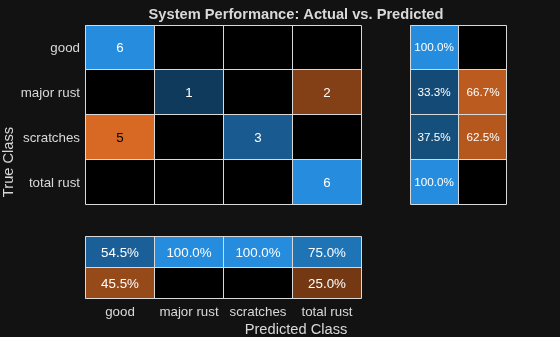

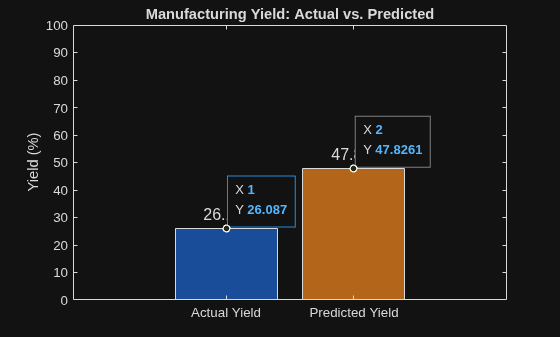

defectTable = 3×3 table
     defectTypes      predictedDefectCounts    actualDefectCounts
    ______________    _____________________    __________________

    {'major rust'}              1                      3         
    {'scratches' }              3                      8         
    {'total rust'}              8                      6         


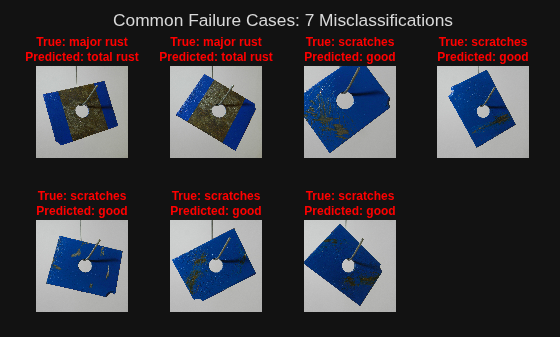

% Here, it is recommended to create a separate runInspectionSuite.m file
% (or include as a local helper function) that combines the work you've done 
% so far here and additionally performs the steps outlined in the task description. 
% You can run it from here.
function RunInspectionSuite(imgDS)
    % Splits the given datastore into training, validation, and testing
    [imgDSTrain, imgDSValidation, imgDSTest] = splitEachLabel(imgDS,0.6,0.15,0.25,"randomized");

    % Loading the recommended pretrained network 
    net = imagePretrainedNetwork("resnet18", NumClasses=4);
    
    % Since resnet can only use 224x224 images, resize the data stores using
    % augmentedImageData
    augTrain = augmentedImageDatastore([224 224 3], imgDSTrain);
    augValidation = augmentedImageDatastore([224 224 3], imgDSValidation);
    
    % Sets the training options for the pretrained network
    options = trainingOptions("adam", ...
        ValidationData=augValidation, ...
        InitialLearnRate=1e-4, ... 
        ValidationFrequency=2, ...
        Plots="none", ... SET TO training-progress LATER
        MaxEpochs=3, ... SET TO 30 LATER
        Metrics="accuracy", ...
        Verbose=false);
    
    % Fine tune the network for this case
    trainedNet = trainnet(augTrain, net, "crossentropy", options); % This is the main network that will be used
    
    % Some basic metrics on the test datastore
    numTestImages = length(imgDSTest.Files);
    actualLabels = imgDSTest.Labels;
    predictedLabels = strings(numTestImages, 1);

    % All the outputs for each image (Both AI and Evidence data stored here)
    finalLabels = cell(numTestImages); % .classBased or .simplified
    confidenceScores = zeros(numTestImages, 1);
    evidenceOverlays = cell(numTestImages, 1);
    evidenceMetrics = cell(numTestImages); % .numComponents, .maxArea, or .areaRatio
    baselineDecisions = cell(numTestImages); % .evidence or .AI

    % Get predictions from all test images
    for i = 1 : numTestImages
        img = readimage(imgDSTest, i);
        [finalLabels{i}, confidenceScores(i), ...
            evidenceOverlays{i}, evidenceMetrics{i}, ...
            baselineDecisions{i}] = InspectPart(img, trainedNet);
        predictedLabels(i) = finalLabels{i}.classBased;
    end
    % Clean current labels to get rid of _, as it messed with confusion matrix formatting
    currentCats = categories(actualLabels);
    cleanCats = strrep(currentCats, '_', ' ');

    % Convert to categorical arrays for the confusion matrix ALSO rename
    % for clean showing
    predictedLabelsCat = categorical(predictedLabels, categories(actualLabels));
    actualLabels = renamecats(actualLabels, cleanCats);
    predictedLabelsCat = renamecats(predictedLabelsCat, cleanCats);

    % Generate a confusion matrix
    figure;
    confusionchart(actualLabels, predictedLabelsCat, ...
        "Title", "System Performance: Actual vs. Predicted", ...
        "RowSummary", "row-normalized", ...
        "ColumnSummary","column-normalized");

    isPassActual = (actualLabels == "good");
    isPassPredicted = (predictedLabelsCat == "good");

    % Calculate the yields based on the true labels (actualLabels) and
    % those predicted by the AI (predictedLabelsCat)
    totalParts = numTestImages;
    actualYield = sum(isPassActual) / totalParts * 100;
    predictedYield = sum(isPassPredicted) / totalParts * 100;

    %
    % Display the yield in a bar chart
    %
    figure;
    yieldBarChart = bar([actualYield, predictedYield]);
    yieldBarChart.FaceColor = "flat";
    yieldBarChart.CData(1,:) = [0.1 0.3 0.6];
    yieldBarChart.CData(2,:) = [0.7 0.4 0.1];

    ylim([0 100]);
    ylabel("Yield (%)");
    title("Manufacturing Yield: Actual vs. Predicted");
    xticklabels({"Actual Yield", "Predicted Yield"});

    % Display the actual percentages
    text(1, actualYield + 5, sprintf("%.1f%%", actualYield), "HorizontalAlignment", "center", "FontSize", 12);
    text(2, predictedYield + 5, sprintf("%.1f%%", predictedYield), "HorizontalAlignment", "center", "FontSize", 12);
    
    %
    % Summarize counts of predicted defects
    %
    predictedDefects = predictedLabelsCat(predictedLabelsCat ~= "good");
    predictedDefectCounts = countcats(predictedDefects);
    defectTypes = categories(predictedDefects);

    % Summarize counts of ACTUAL defects
    actualDefects = actualLabels(actualLabels ~= "good");
    actualDefectCounts = countcats(actualDefects);
    
    % Removes the good from the table
    predictedDefectCounts(1) = [];
    defectTypes(1) = [];
    actualDefectCounts(1) = [];

    % Displays the defects
    defectTable = table(defectTypes, predictedDefectCounts, actualDefectCounts);
    defectTable
    
    %
    % Display a montage of common failure cases
    %
    misclassifiedIdx = find(actualLabels ~= predictedLabelsCat);

    if ~isempty(misclassifiedIdx)
        numErrors = length(misclassifiedIdx);
        
        figure; % Went with a tiled layout because it seemed easier to add a title to the pictures

        t = tiledlayout("flow", "TileSpacing","compact", "Padding","compact");
        title(t, sprintf("Common Failure Cases: %d Misclassifications", numErrors));

        for k = 1 : numErrors
            idx = misclassifiedIdx(k);
            img = readimage(imgDSTest, idx);

            nexttile;
            imshow(img);
            titleStr = sprintf("True: %s\nPredicted: %s", string(actualLabels(idx)), string(predictedLabelsCat(idx)));
            title(titleStr, "Color", "red", "FontSize", 9, "Interpreter", "none");
        end

    else
        disp("No misclassifications found in the test set.");
    end
end

### Evaluation

% 
RunInspectionSuite(partsBS);

## Task 5: Test and Evaluate System Robustness

Your goal in this step is to assess how your system performs under simulated variations. You can simulate image inspection station variation by altering the lighting, blur, or noise in the images. Here are some suggested distortions to apply:

- Brightness/contrast: `imadjust(...)`

- Blur: `imgaussfilt(...)`

- Noise: `imnoise(...)`

Then, re-run the evaluation. In other words, run `runInspectionSuite.m `again with the same image set after applying distortions to the images.

Compare how performance changes across conditions by reporting how accuracy and false-reject rates change under simulated variations.

% Insert your code here (or make use of helper functions or additional .m or .mlx files and indicate where
% they can be found). Ensure your code is well-documented.




## Interpretation of Results

Summarize your findings by interpreting their physical/engineering meaning:

What are some limitations of your work?

What are practical next steps?